%Dimensions of the House



xStart = 0;%Ignored Base is ALWAYS (0|0) for Symmetry Reasons
yStart = 0;
height = 8;
width = 8;
margin = 0.5;

%Critical Point
xC = 4;
yC = 4;

%Door
doorW = 1;
doorH = 2;

%Window
windW = 1.5;
windH = 1.5;
windMargin = 0.25;

	%Helping Variables
	ww = windW + 2 * windMargin; %window Width and margin
	wh = windH + 2 * windMargin;
	%For House
	rw = width - 2 * margin; %real width
	rh = height - margin; %real height
    




tries = 200;
data = 0;
n = 10000;
nDa = zeros(1,n);
DataMatrix = zeros(n,20,5);
size(DataMatrix)

ans =        10000          20           5


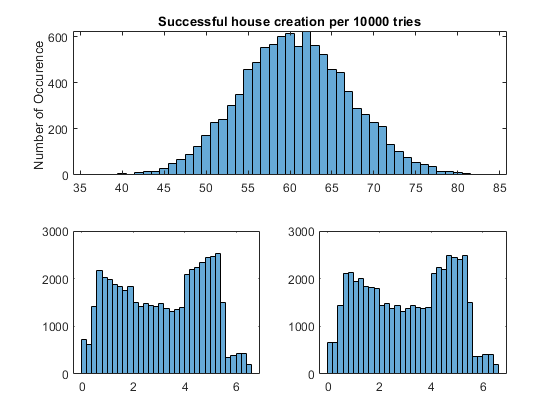

for l = 1:n

for k = 1:tries
    doorX = margin + rand()* (rw-doorW);
    door = [doorX 0 doorW doorH];
    windX1 = margin + rand()* (rw-ww);
    windY1 = rand() * (rh-wh);
    window1 = [windX1 windY1 ww wh];
    if ~doorIsInWindow(window1, door) && ~critIsInWindow(window1, [xC yC])
        windX2 = margin + rand()* (rw-ww);
        windY2 = rand() * (rh-wh);
        window2 = [windX2 windY2 ww wh];
        
        if ~doorIsInWindow(window2, door) && ~windowInwindow(window1, window2) && ...
                ~critIsInWindow(window2, [xC yC])
%             figure();
%             plotSquare(xStart, yStart, width, height,[0 0 0]);
%             hold on
%             plotSquare(xStart + margin,yStart,rw,rh,'r'); %Margin
%             plot(xC,yC,'go')
%             plotSquare(doorX,yStart, doorW, doorH, [0.5 0.5 0.5]);
%             plotSquare(windX1 +windMargin, windY1+windMargin, windW, windH, [0.2 1 0.2]);
%             plotSquare(windX2 +windMargin, windY2+windMargin, windW, windH, [0.2 0.2 0.5]);  
            data = data + 1;
            DataMatrix(l,data,:) = [doorX windX1 windY1 windX2 windY2];
%             
%             axis([-1 9 -0.5 9.5])
        end
    end
end
nDa(l) = data;
data = 0;
end
subplot(2,1,1);
histogram(nDa);
title("Successful house creation per " + num2str(n) + " tries")
ylabel("Number of Occurence ")

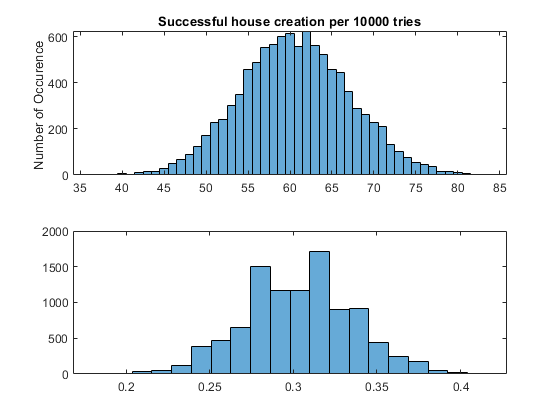

subplot(2,1,2);
title("Percentage of success")
histogram(nDa./tries,20);

% figure;
% subplot(2,2,1);
% histogram(DataMatrix(:,1,:));
% subplot(2,2,2);
% histogram(DataMatrix(:,2,:));
% subplot(2,2,3);
% histogram(DataMatrix(:,3,:));
% subplot(2,2,4);
% histogram(DataMatrix(:,4,:));


